graphs = init_population(15, 100);
graphs

graphs = 1×100 cell 数组
    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {15×15 double}    {

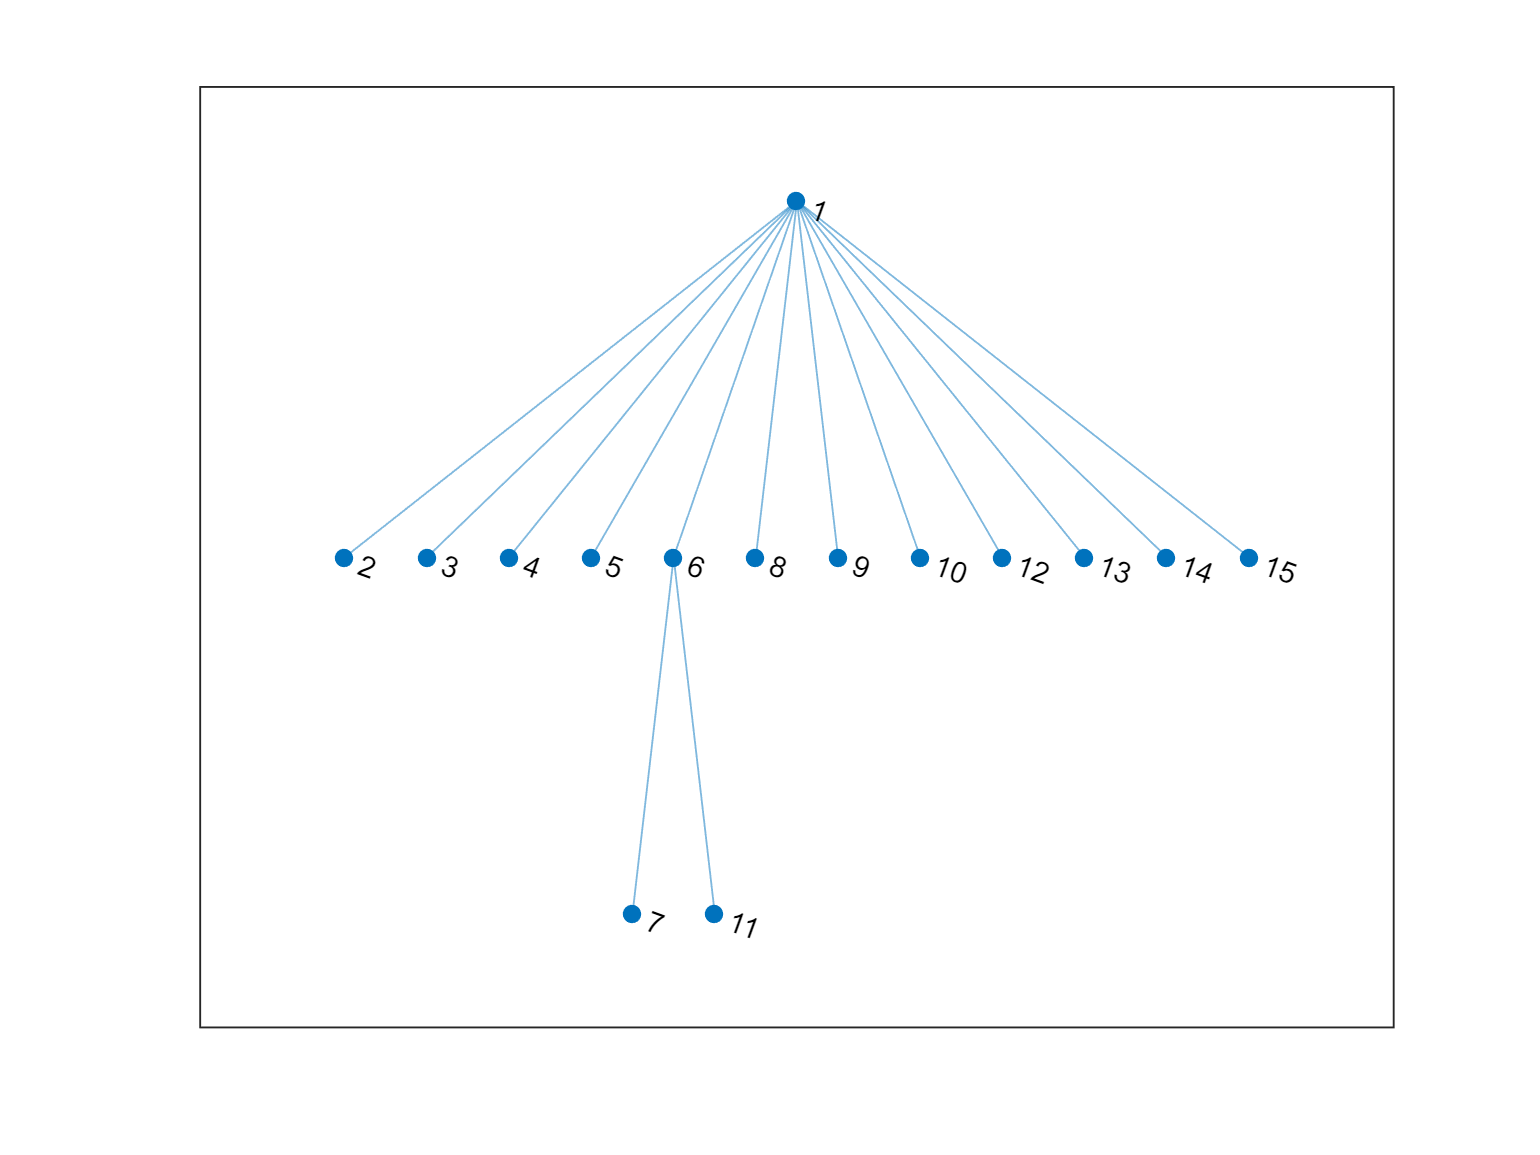

[bestGraph, bestFw] = EA_weighted_fitness(15, 0.3, 0.3, 1, 1, 1);
plot(graph(bestGraph))

[bestGraph, bestFit] = EA(15, 0.3, 0.3)

bestGraph =      0     0     0     0     1     0     0     0     0     0     0     0     0     0     1
     0     0     1     0     0     0     1     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1     1     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     1     0     0     0
     0     0     0     1     0     0     0     1     0     0     0     0     0     0     0
     0     1     0     1     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     0     0     0     1     0     0     1     0     0
     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0


bestFit = 8.6667

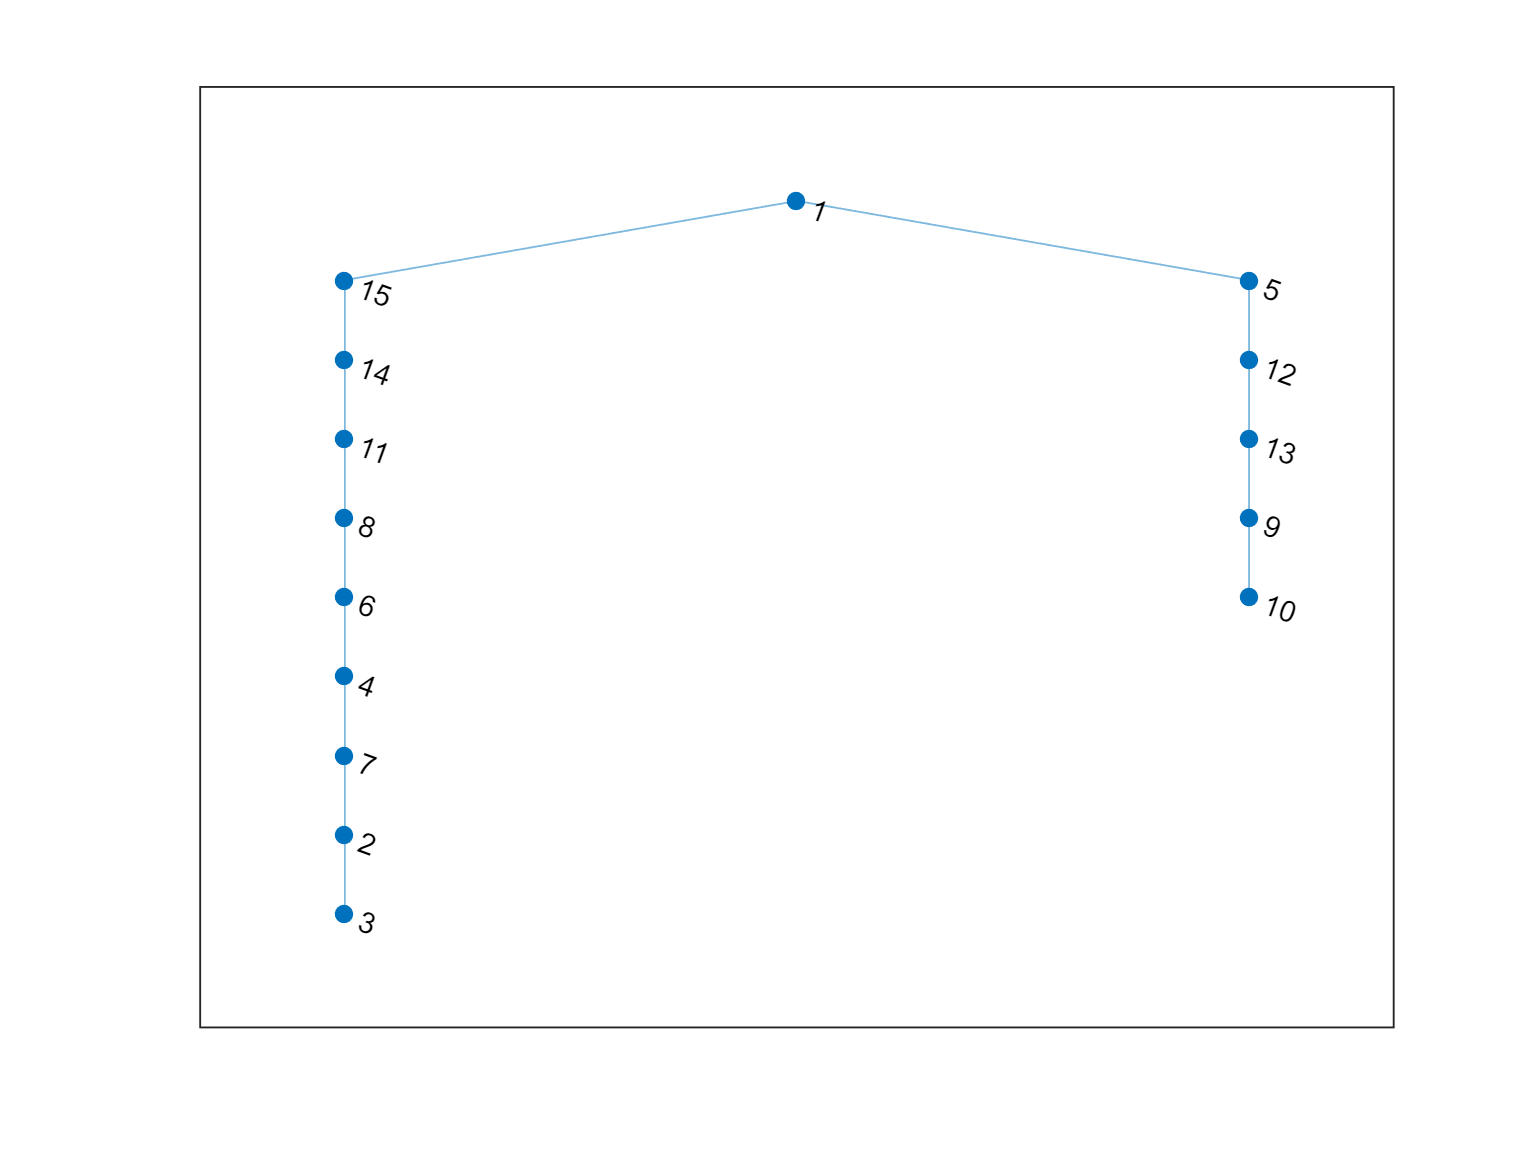

plot(graph(bestGraph))

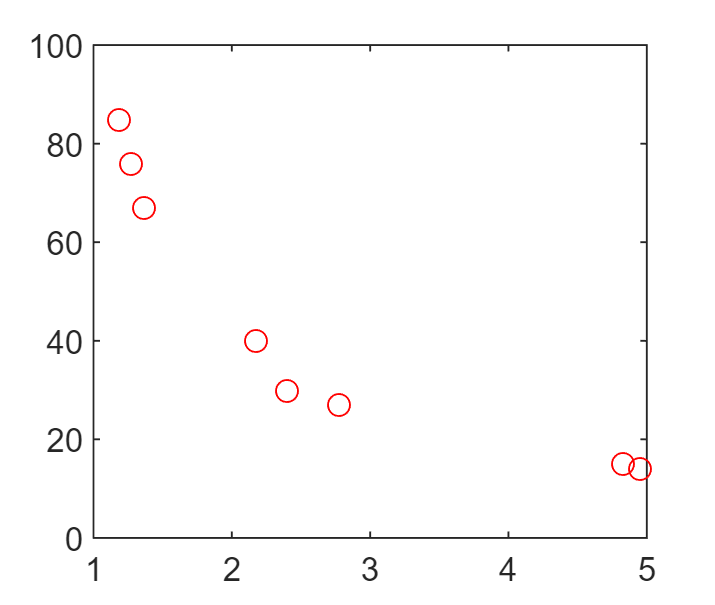

[bestSolutions, multiFitValues] = MOEA(15, 0.05, 0.05);
f1 = ones(1, 100)./multiFitValues{1};
f2 = ones(1, 100)./multiFitValues{2};
f3 = ones(1, 100)./multiFitValues{3};
% f1 = multiFitValues{1};
% f2 = multiFitValues{2};
% f3 = multiFitValues{3};
set(gcf,'Position',[100 100 260 220]);

[allFronts, ~] = non_dominated_sorting(bestSolutions);
for i = 1 : 10
    fprintf("" + f1(i) + " , " + f2(i) + " , " + f3(i) + "\n");
end

4.7048 , 12 , 15
4.7238 , 12 , 14
1.2 , 2 , 84
4.7238 , 12 , 14
1.2 , 2 , 84
1.3238 , 2 , 71
1.5619 , 3 , 55
1.619 , 3 , 50
1.7333 , 4 , 46
4.3238 , 11 , 16


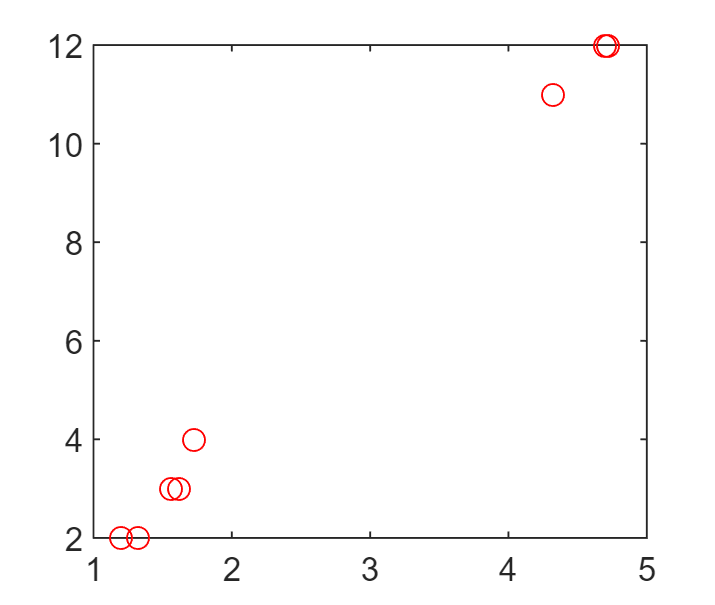

plot(f1(1 : 10), f2(1 : 10), 'ro');

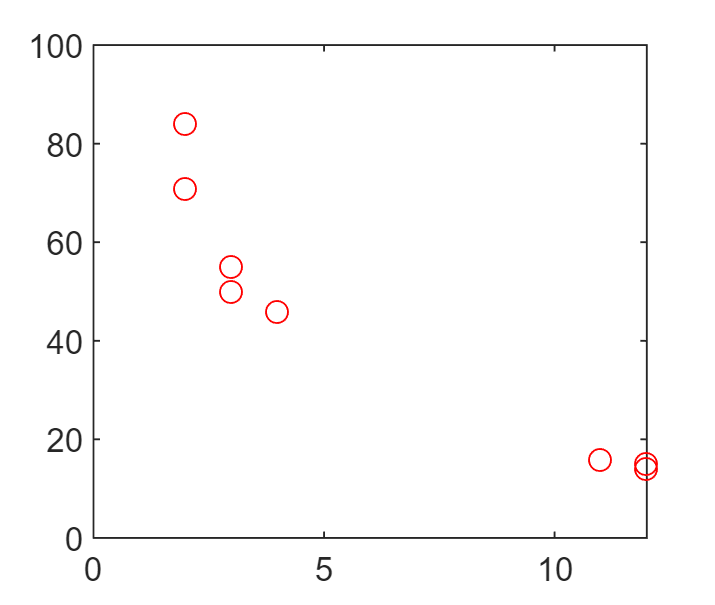

plot(f2(1 : 10), f3(1 : 10), 'ro');

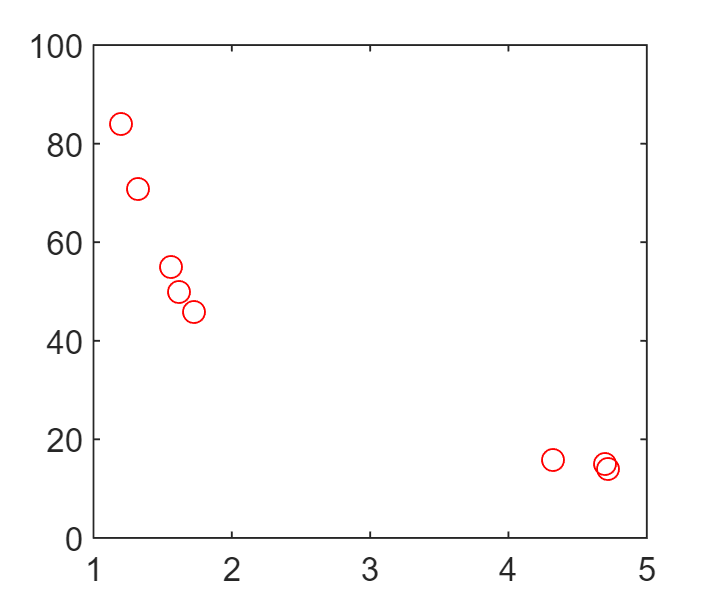

plot(f1(1 : 10), f3(1 : 10), 'ro');

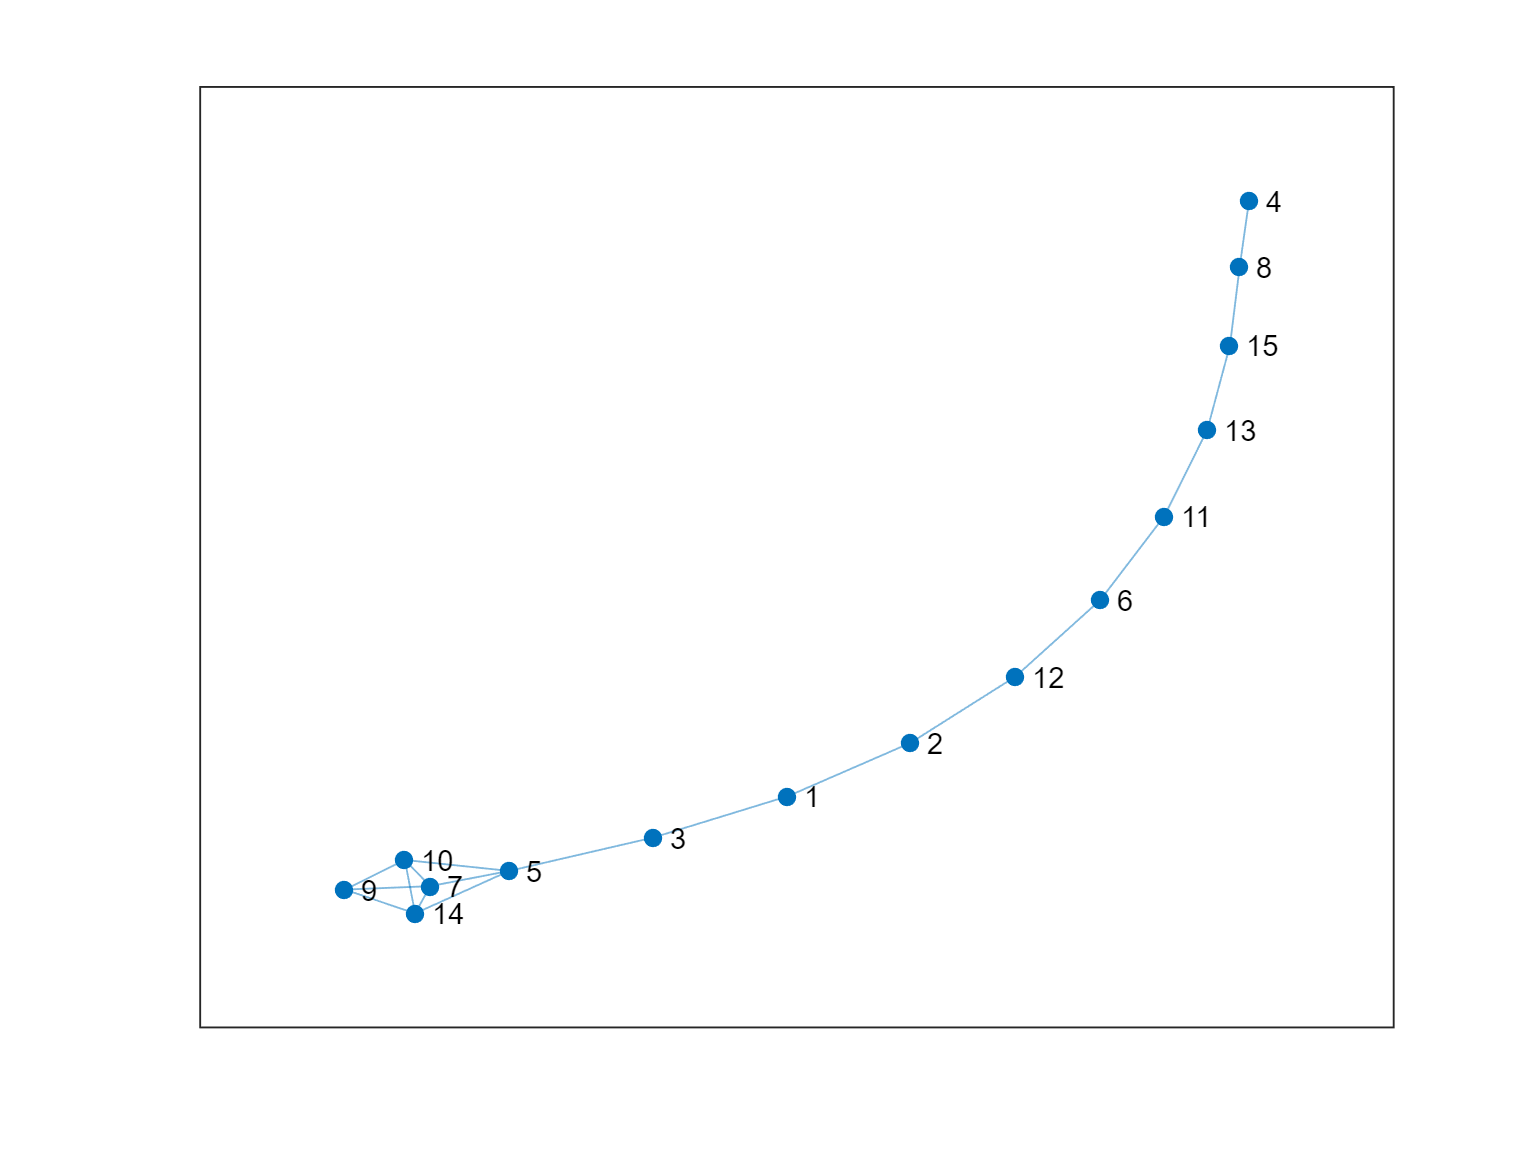

plot(graph(bestSolutions{10}))

[~] = non_dominated_sorting(graphs);
offGraphs = mutation(graphs, 0.3, 0.2);
comPop = [graphs, offGraphs];

[allFronts, ~] = non_dominated_sorting(comPop)
crowDists = crowding_distance(comPop, allFronts)
newPop = elite_preservation(comPop, 100, allFronts, crowDists)
[allFronts, popRank] = non_dominated_sorting(newPop)
multiFitValues = multi_obj_fitness(newPop);

bestGraph = EA(15, 0.3, 0.3);
fprintf("" + (cal_diameter(bestGraph) - cal_avg_path_len(bestGraph)) + "\n");

cal_avg_path_len([0, 1, 0, 1; 1, 0, 1, 0; 0, 1, 0, 1; 1, 0, 1, 0])

[bestSolutions, bestMultiFitValues] = MOEA(15, 0.3, 0.3);
f1 = ones(1, 100)./bestMultiFitValues{1}
f2 = ones(1, 100)./bestMultiFitValues{2}
f3 = ones(1, 100)./ bestMultiFitValues{3}

plot(f1(1:10), f2(1:10), "b-o");